clear all

t = (0:0.01:0.99)'

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900



timesteps = 20

timesteps = 20


t=linspace(0,1,timesteps+1)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


t(end)=[];

M = 0.5*[1 -2 1; -2 2 1; 1 0 0];

knots = 10

knots = 10

index= [];

output1 = sin(exp(t)+sin(10*t).^2+3*cos(3*t)+0.3*rand(timesteps,1));
output2= cos(5*t)+0.4*rand(timesteps,1)

output2 =     1.2714
    0.9804
    1.1814
    0.8019
    0.7643
    0.5282
    0.1923
    0.1018
   -0.0353
   -0.4103



output_curve = outproduct(output1,output2);

Y = output_curve(:)

Y =    -1.0505
   -1.1913
   -1.2695
   -1.2527
   -1.2714
   -1.0528
   -0.3223
   -0.1196
   -0.3606
   -0.2671


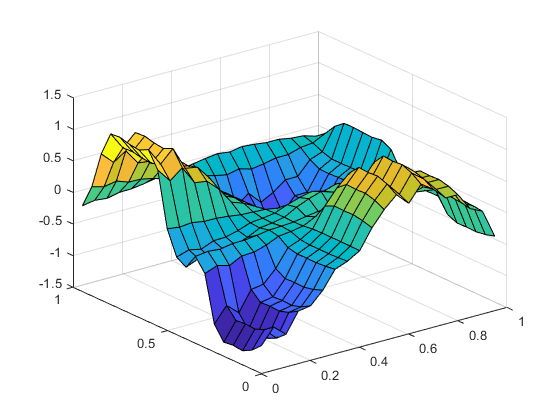





% output_curve(1:80,1:80)=0
surf(t,t,output_curve);

% 
% plot(output1)
% plot(output2)

N=zeros(length(t),knots+2);
B=[]


B =

     []



C=[]


C =

     []




for i=1:length(t)
   index(i)= floor((t(i)*knots+(10*knots*eps)))+1;
    Ntemp = (mod(t(i),1/knots)*knots).^linspace(2,0,3)*M';
%     Ntemp = (t(i)-(index(i)-1)/timesteps/knots).^linspace(2,0,3)*M';
    N(i,index(i):index(i)+2) = Ntemp;
end

for ii= 1:timesteps
    for jj=1:timesteps

N_multi = outproduct(N(ii,:),N(jj,:));

N_T{(ii-1)*timesteps+jj}= [N(ii,:);N(jj,:)];

   B(jj,:)=N_multi(:)';
    end
    C = [C ; B];
end


% -------------------------------------
tic
Theta=zeros((knots+2)^2,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye((knots+2)^2)*10000

Pcov =        10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0       10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        



for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsilo(kk) = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsilo(kk);

end

toc

Elapsed time is 0.131649 seconds.


% -----------------------------------
tic
P=pinv(C)*output_curve(:);
toc

Elapsed time is 0.011931 seconds.



tol=10^-4

tol = 1.0000e-04

lambda=0.95

lambda = 0.9500


d=2

d = 2

n=(knots+2)

n = 12

l=1

l = 1


sigmas= [10000]

sigmas = 10000


PcovT=initP(sigmas,n,d)

PcovT = struct with fields:
       n: [2×5 double]
    core: {[12×12 double]  [12×12 double]}


PcovT.n

ans =      1    12    12     1     1
     1    12    12     1     1


ttcontractkim(PcovT)

ans =        10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0       10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0         


XT=initm(l,n,d)

XT = struct with fields:
       n: [2×4 double]
    core: {[0 0 0 0 0 0 0 0 0 0 0 0]  [0 0 0 0 0 0 0 0 0 0 0 0]}


XT.core

ans = 1×2 cell array
    {1×12 double}    {1×12 double}


XT.n

ans =      1    12     1     1
     1    12     1     1


% ttcontractkim(XT)

% ------------------------------------
for epochs=1:1
    
indexez= randperm(400);    
    
    if epochs>1
      lambda=1
%     lambda=0.9+epochs/50
    end
    
for kk=1:400

Phi = N_T{indexez(kk)};
f = contractX(XT,Phi);

epsil(kk) = Y(indexez(kk)) - f;

Pc = contractPC(PcovT,Phi,0);
% ttcontractkim(Pc);

cP = contractPC(PcovT,Phi,1);
% ttcontractkim(cP);

cPc = contractX(Pc,Phi);

c=squareTN(Pc,cP);
% ttcontractkim(c);

for j=1:size(c.n,1)
c.core{j} = reshape(c.core{j},c.n(j,:));
end

c.core{1} = c.core{1}*(-1/(lambda+cPc));
% ttcontractkim(c);

PcovT = addTN(c,PcovT);

if mod(kk,1)==0
PcovT = roundTN(PcovT,tol);
end

PcovT = reshapeP(PcovT);
PcovT.core{end}= PcovT.core{end}*lambda;

% ttcontractkim(PcovT)

K = contractPC(PcovT,Phi,0);

K.core{1}= K.core{1}*epsil(kk);
% ttcontractkim(K);

XT = addTN(XT,K);

if mod(kk,1)==0
XT = roundTN(XT,tol);
end

% 

end
end

test =ttcontractkim(XT);

y=C*test;
y=C*P;
y=C*Theta;
y=C*test;

norm(test-P)

ans = 10.0102

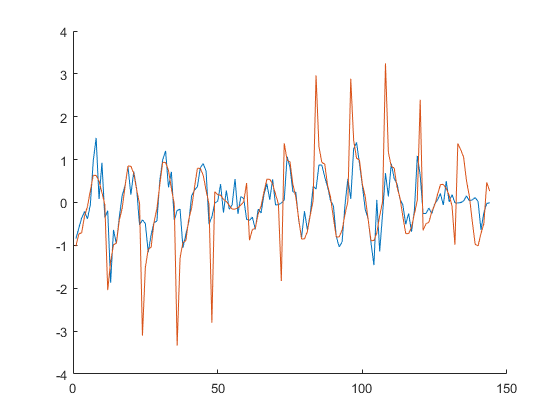


figure;
hold on
plot(test)
plot(Theta)
% plot(P)
hold off

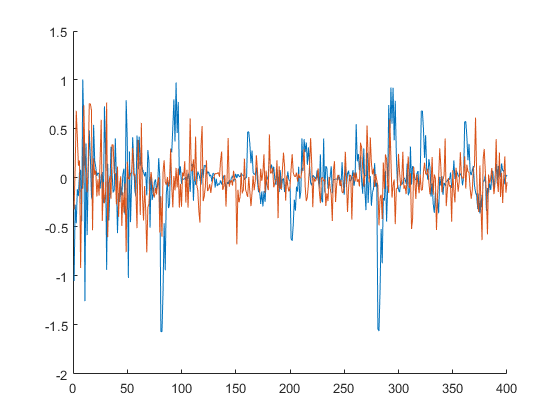


figure;
hold on
plot(epsilo)
plot(epsil)
hold off

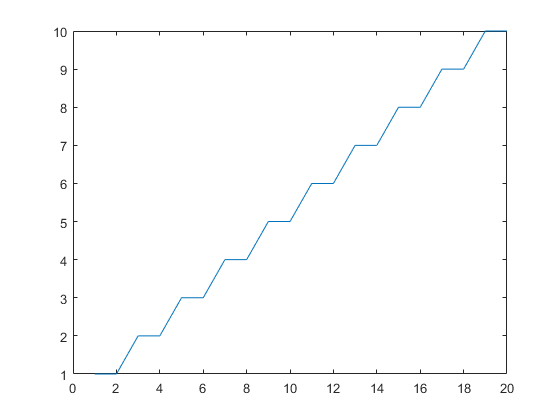


plot(index)

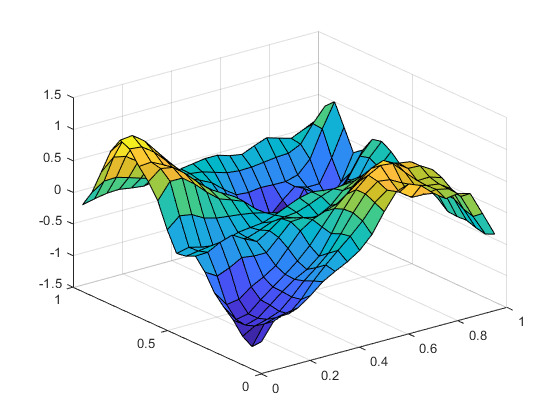

surf(t,t,reshape(y,[timesteps timesteps]))

surf(t,t,output_curve)

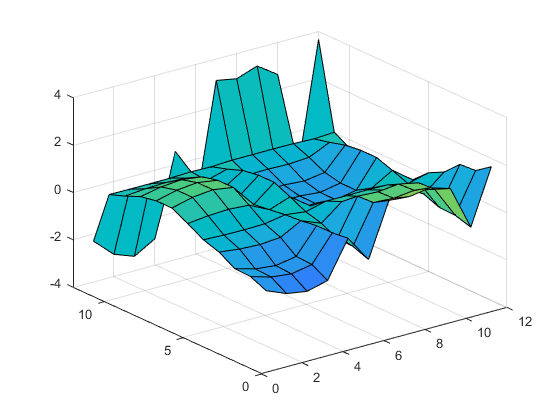


surf(1:knots+2,1:knots+2,reshape(P,[knots+2 knots+2]))


norm(reshape(y,[timesteps timesteps])-output_curve)

ans = 2.0143

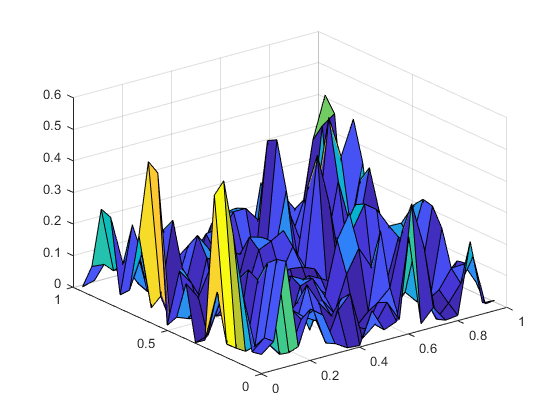


 surf(t,t,abs(reshape(y,[timesteps timesteps])-output_curve))


[coeff,score,latent] = pca(reshape(P,[knots+2 knots+2]))

coeff =    -0.2417    0.4736   -0.2992   -0.4269    0.3189   -0.3468    0.1388   -0.1487    0.0225    0.1718   -0.0870
   -0.3252   -0.2509    0.5965    0.0933    0.2301    0.1860   -0.0151   -0.4063   -0.0790    0.2192   -0.0606
   -0.3584    0.2452   -0.0790    0.1882    0.4396    0.5156   -0.1295    0.4217    0.2576    0.1071   -0.1127
   -0.3055   -0.0137    0.3122   -0.1323   -0.3544   -0.3388   -0.2678    0.5170    0.2417    0.1893    0.2951
    0.0589   -0.1312    0.2117   -0.0500    0.0768   -0.0847    0.5243    0.1458    0.5658   -0.4714   -0.2331
   -0.2077    0.1688   -0.2226    0.0740   -0.3040    0.2230   -0.2937   -0.4947    0.4731   -0.2879    0.2869
    0.3254   -0.1580    0.1015   -0.1104    0.6354   -0.2160   -0.3875   -0.0195    0.1402   -0.2114    0.4225
    0.3081    0.0269   -0.0521   -0.0722   -0.0217    0.3530    0.4650    0.0535    0.1208    0.3972    0.5895
    0.3405   -0.2664   -0.1197   -0.4975   -0.1087    0.3259   -0.3599    0.0754    0.1932    0.1814   -

score =     3.2372    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    2.0270   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
    1.9099    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.2788   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000
   -0.6027    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
   -2.1706   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000
   -3.6225    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
   -3.6078   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000
   -3.0941   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -

latent =    12.3179
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


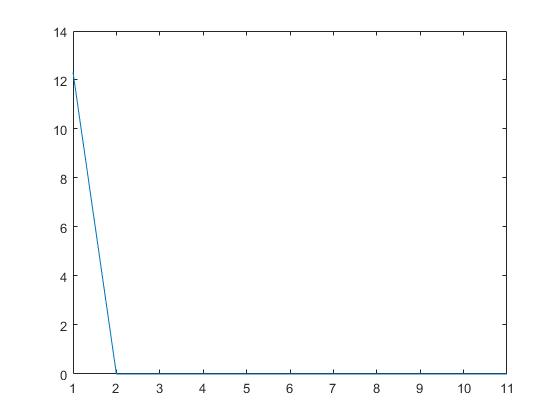


plot(latent)